# **Robotics Fundamentals Lab**

## **Robot Import**

Here, the robot is imported from the created URDF. The Unified Robotics Description Format (URDF) is an extensible markup language (XML) file type used to describe the physical aspects of a robot. Essentially, it serves as a 3-D model that contains information about the robot. This includes a description of the rigid body links which make up the robot, physical properties of these links such as mass, inertia and centre of mass, a description of the joints which connect the links together including the movement limits of these joints, and visual and collision properties of the robot. URDF files are widely used, particularly in ROS, for simulation, visualisation and control.

%Imports URDF file into MATLAB as rigidBodyTree
    irb120 = importrobot('irb120.urdf');
    irb120.DataFormat = 'row';

%Sets robot's home coordinate (All Joints = 0°)
    home = homeConfiguration(irb120);

 

## Initialise Variables

Here, variables are created to store information on the joint configuration of the robot and to set the joint limits of the robot.

jointConfig = zeros(1,6);
joint_1 = jointConfig(1,1);
joint_2 = jointConfig(1,2);
joint_3 = jointConfig(1,3);
joint_4 = jointConfig(1,4);
joint_5 = jointConfig(1,5);
joint_6 = jointConfig(1,6);

joint_1_LowerLim = -165;
joint_2_LowerLim = -110;
joint_3_LowerLim = -110;
joint_4_LowerLim = -160;
joint_5_LowerLim = -120;
joint_6_LowerLim = -400;

joint_1_UpperLim = 165;
joint_2_UpperLim = 110;
joint_3_UpperLim = 70;
joint_4_UpperLim = 160;
joint_5_UpperLim = 120;
joint_6_UpperLim = 400;

 

%% Forward Kinematics

### **Forward Kinematics (FK)**

For industrial robots, forward kinematics are used to find the position of the end-effector relative to some base coordinate frame for a given joint configuration. To compute the forward kinematics, the DH parameters can be used.

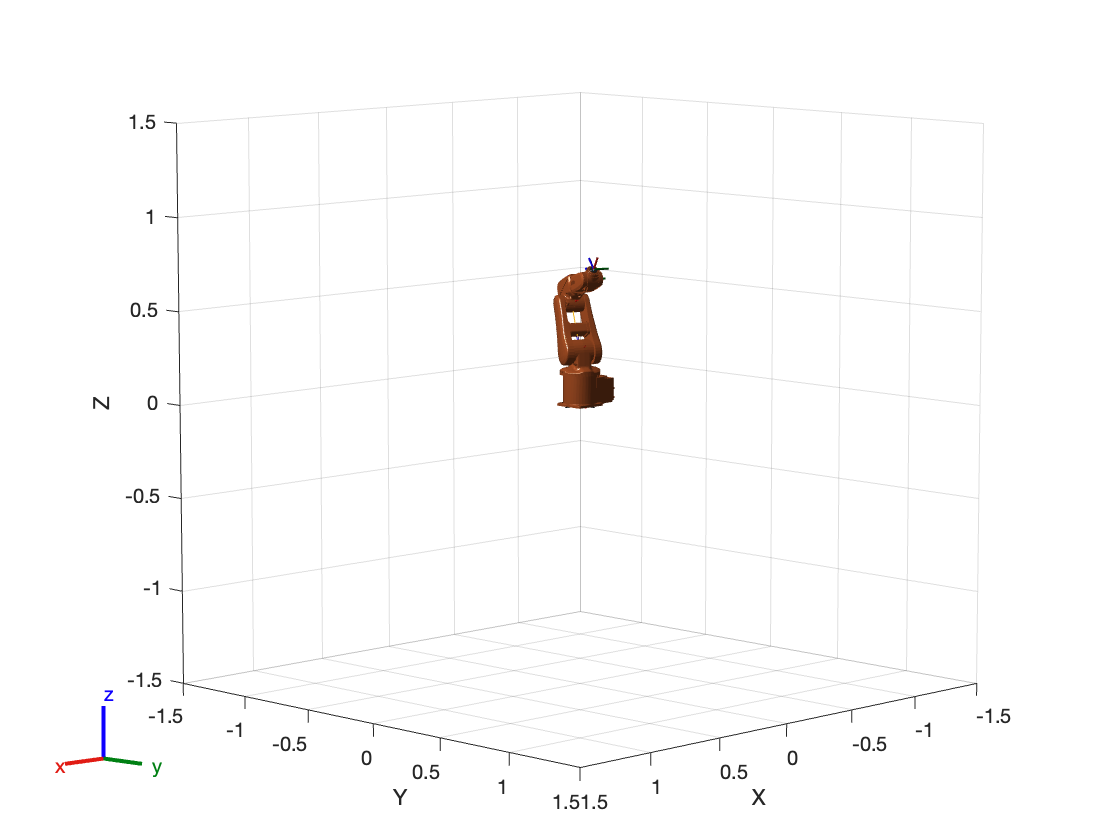

irb120.DataFormat = 'row';

jointConfig(1,1) = deg2rad(67);
jointConfig(1,2) = deg2rad(-26);
jointConfig(1,3) = deg2rad(8.51);
jointConfig(1,4) = deg2rad(0);
jointConfig(1,5) = deg2rad(-34.41);
jointConfig(1,6) = deg2rad(0);

 

figure(1);
show(irb120,jointConfig);

eePos = getTransform(irb120,jointConfig,'link_6');
X = eePos(1,4)

X = 0.0754

Y = eePos(2,4)

Y = 0.1777

Z = eePos(3,4)

Z = 0.7469

Rotations = tform2quat(eePos)

Rotations =     0.7498    0.2415   -0.3649    0.4963


isColliding = checkCollision(irb120,jointConfig,SkippedSelfCollisions="parent");
if isColliding
   Collision_Detected = 'Self-Collision Detected';
   disp(Collision_Detected);
else
    Collision_Detected = 'No Self-Collision';
    disp(Collision_Detected);
end

No Self-Collision


## Inverse Kinematics (IK)

Inverse kinematics is the reverse of forward kinematics, finding the joint angles needed to achieve a desired end effector pose. Contrary to forward kinematics, the problem of inverse kinematics is not simple and there is no universal solution that can be used for all types of manipulators. Furthermore, different geometrical layouts of the manipulator can lead to numerous configurations or solutions for a specified position and orientation. For example, any general 6 DOF manipulator comprised of 6 revolute joints will at most 16 solutions to any desired pose. However, for the IRB 120 there are only 4 configurations due to mechanical restrictions. These configurations are defined as:

- **Elbow Up**

- **Elbow Down**

- **Wrist Up**

- **Wrist Down**

#### Analytical Solver

For robots with closed-form solutions, analytical methods will yield much faster solve times. For a manipulator to have a closed-form solution, it must have one of several configurations. One such configuration is for robots with a spherical wrist. This is the case for the ABB IRB 120 with the last 3 joints making a spherical wrist. The full derivation of the solution can be found here: [AIK Derivation](https://www.set-science.com/manage/uploads/ISAS2019-ENS_0042/SETSCI_ISAS2019-ENS_0042_0072.pdf)

irb120.DataFormat = 'row';    

%Selects kinematic group for the IK solver
    aik = analyticalInverseKinematics(irb120);
    
%Generates the analytical IK function
    generateIKFunction(aik, 'irbAIK');

#### Numerical Solver

Contrary to analytical methods that use closed-form solutions, numerical techniques estimate the joint angles required to reach a desired end effector position through iterative calculations. There are many different methods to solve the inverse kinematics problem numerically. The Levenberg-Marquardt Method will be used in this instance. It is an error-damped least-square method which combines aspects of the Gauss-Newton method and gradient descent. Given a desired end effector pose, this method interactively solves the Jacobian matrix, which relates joint velocities to end effector velocities, from an initial guess of the required joint angles. The closer this guess is to the desired joint angles, the faster the solution will converge. This makes it an efficient method for solving the inverse kinematics along a path with many waypoints. Additionally, it handles non-linearities and singularities that may arise in challenging cases.

%Initialises IK solver using Levenberg-Marquardt Method
    robotNIK = inverseKinematics("RigidBodyTree",irb120, "SolverAlgorithm",'LevenbergMarquardt');

%Define weightings for IK solver. This will tell the solver which parameters of the pose to solve
    weights = [1 1 1 1 1 1]; % [roll pitch yaw X Y Z]

%Define initial guess as robot's home configuration. (All joints = 0°)
    initialguess = home;

#### Use Inverse Kinematics Solvers

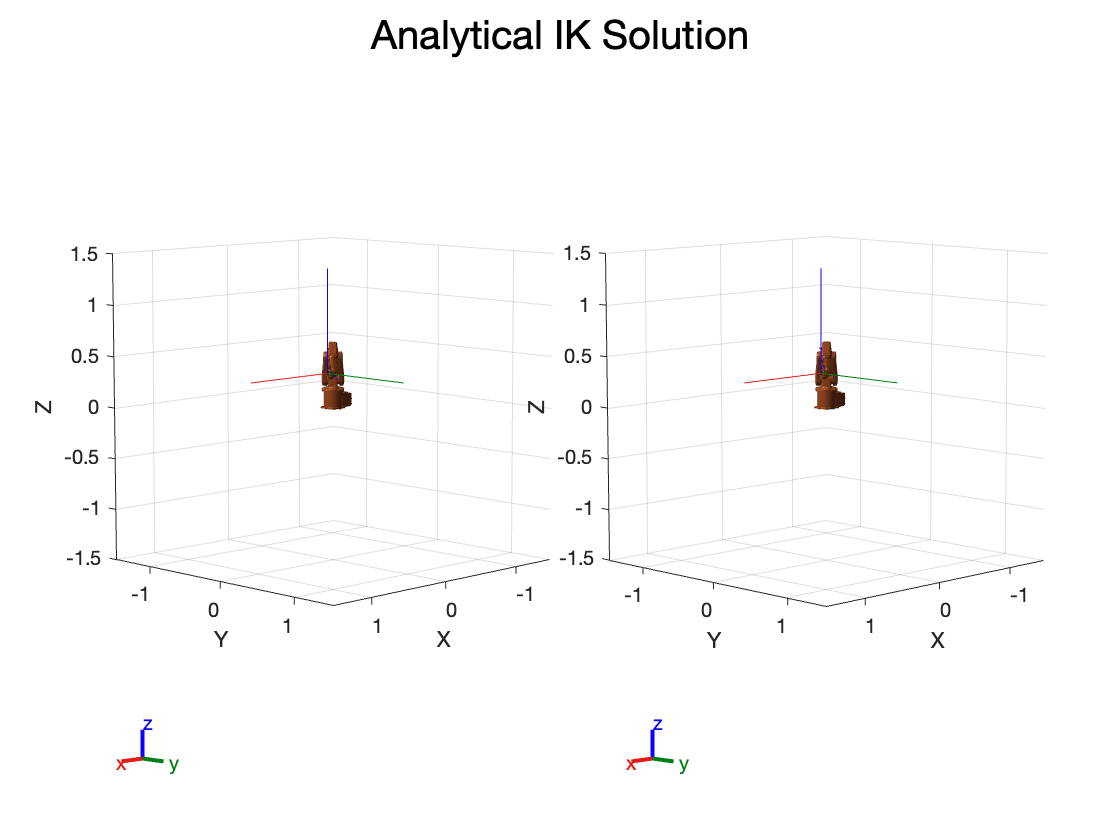

% Select desired coordinates for end-effector
    X = 0.374;
    Y = 0.3;
    Z = 0.4;

% Input desired end-effector orientation using quaternion parameters
    q0 = 1;
    q1 = 0;
    q2 = 0;
    q3 = 0;

     

% Create Homogeneous Transformation Matrix from desired pose
    eePos = trvec2tform([X Y Z]);
    eeRot = quat2tform([q0 q1 q2 q3]);
    eePose = eePos * eeRot;

% Solve IK with Analytical Solver
    AIKconfig = irbAIK(eePose);
    
% Solve IK with Numerical Solver
    [NIKconfig, solnInfo] = robotNIK("link_6",eePose,weights,initialguess);

% Display Robot
    figure(2)
    for i = 1:1:size(AIKconfig,1)
        subplot(1,size(AIKconfig,1),i);
        show(irb120,AIKconfig(i,:));
        hold on
        %Plots the end effectors coordinate frame
        plotTransforms(tform2trvec(eePos),tform2quat(eePose))
        hold off
    end
    sgtitle('Analytical IK Solution','FontSize',20)

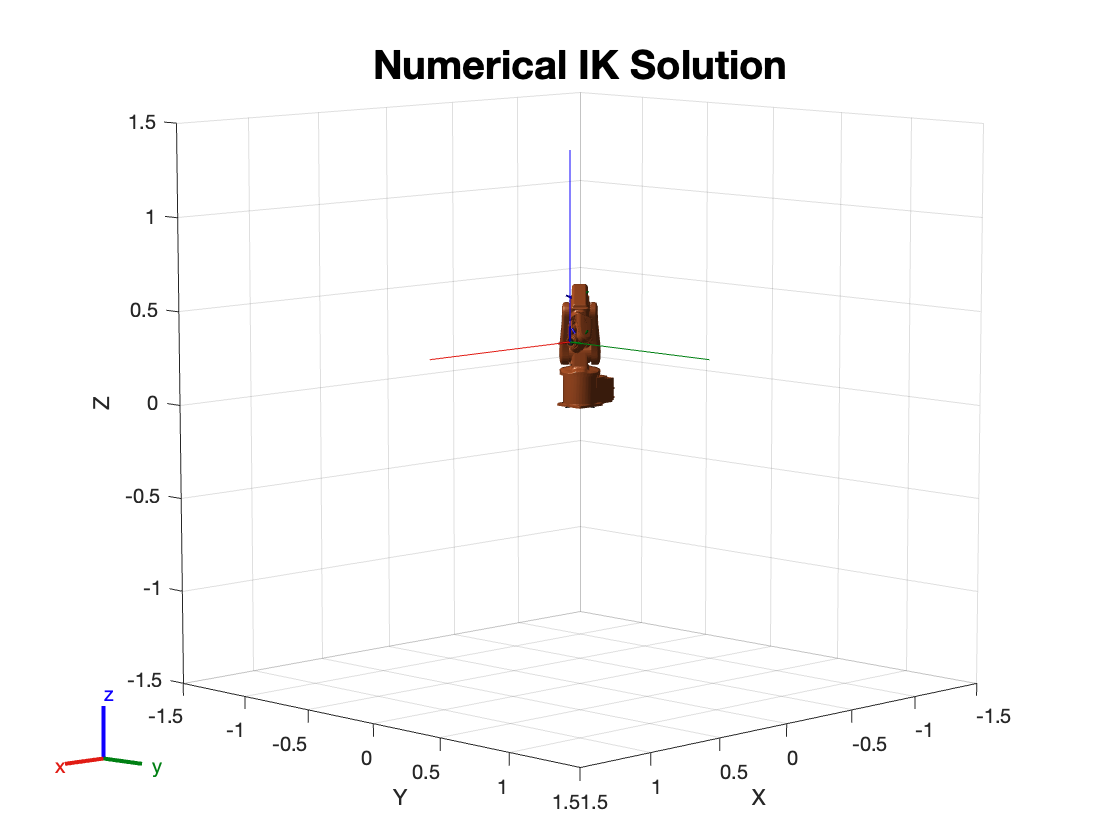


    figure(3);
    show(irb120,NIKconfig);
    title('Numerical IK Solution','FontSize',20);
    hold on
    %Plots the end effectors coordinate frame
    plotTransforms(tform2trvec(eePos),tform2quat(eePose))
    hold off

## Comparing Solver Speed

As stated above, the benefir of using the analytical inverse kinematics solver is the faster solve times it produces over any numerical method. But how much faster can it solve for a given solution? Here, we will examine the solving speeds of each solver for a range of input configurations.

irb120.DataFormat = 'row';
    
configNumber =  100;

% Solve for all Configurations with Analytical Solver
tic
for i = 1:1:configNumber
    randConfig = irb120.randomConfiguration;
    randTform = getTransform(irb120,randConfig,"link_6");
    soln = irbAIK(randTform);
end
AIKspeed = toc;

% Solve for all Configurations with Numerical Solver
tic
for i = 1:1:configNumber
    randConfig = irb120.randomConfiguration;
    randTform = getTransform(irb120,randConfig,"link_6");
    [configsoln, solnInfo] = robotNIK("link_6",randTform,weights,initialguess);
end
NIKspeed = toc;

fprintf('Analytical Solve Time = %.3f seconds', AIKspeed);

Analytical Solve Time = 0.356 seconds

fprintf('Numerical Solve Time = %.3f seconds', NIKspeed);

Numerical Solve Time = 2.400 seconds

## Path Planning

A path is a series of points or configurations that a robot should travel through. These waypoints establish a direct path for the robot to follow from its initial position to the desired destination, promoting smooth and obstacle-free motion. A path is a purely geometrical description of a robot’s movement. To generate these paths, various path planning algorithms can be employed.

Here, a sampling-based algorithm known as bi-directional RRT (Rapidly-Exploring Random Tree) will be used. RRT constructs a tree by iteratively adding new states. In each iteration, RRT randomly samples a state and adds it to the tree by connecting it to the nearest state in the tree. This process results in a tree that rapidly explores the state space. The Bi-Directional RRT search algorithm constructs two trees simultaneously, one from the starting point and one from the target point. These two trees grow towards each other, leading to faster convergence and shorter paths. A visualisation of this is shown below. A video explaining this process can be found here: [Path Planning Explainer](https://uk.mathworks.com/videos/autonomous-navigation-part-4-path-planning-with-a-and-rrt-1594987710455.html)

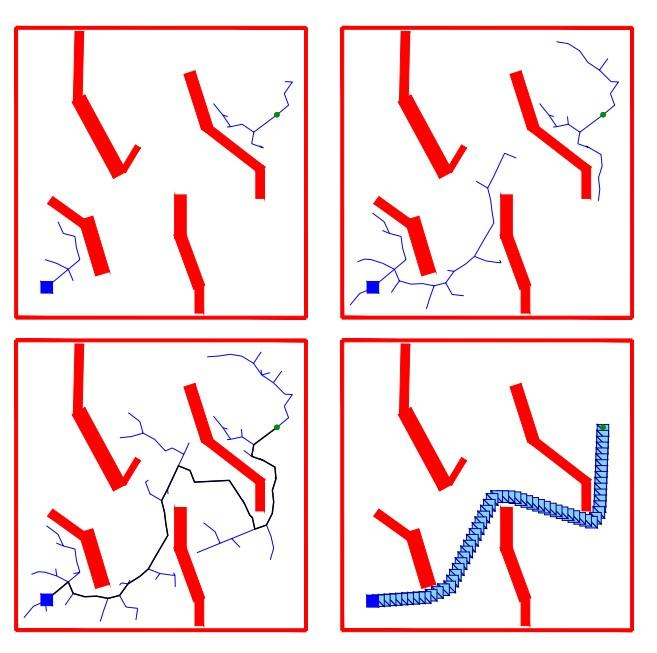

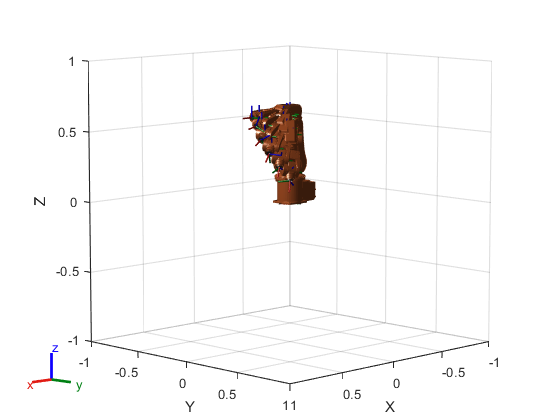

irb120.DataFormat = 'row';

% Create RRT Planner
    rrt = manipulatorRRT(irb120,{});
    rrt.SkippedSelfCollisions = "parent";

% Define Start and End Configuration
    startConfig = home;
    endConfig = irb120.randomConfiguration;

% Check for Self-Collision for End Configuration
    isColliding = checkCollision(irb120,endConfig,'SkippedSelfCollisions','parent');
    while isColliding == 1
        endConfig = irb120.randomConfiguration;
        isColliding = checkCollision(irb120,endConfig,'SkippedSelfCollisions','parent');
    end

% Genrate Path
    path = plan(rrt, startConfig, endConfig);

% Interpolate Configurations along the generated path
    intPath = interpolate(rrt,path);

% Display Robot at various configurations along the path
    figure(4)
    for i = 1:60:size(intPath,1)
        show(irb120,intPath(i,:));
        hold on
    end
    hold off

## Animate Generated Path

Here, we will see how to create an animation of the robot travelling along the path generated in the last section.

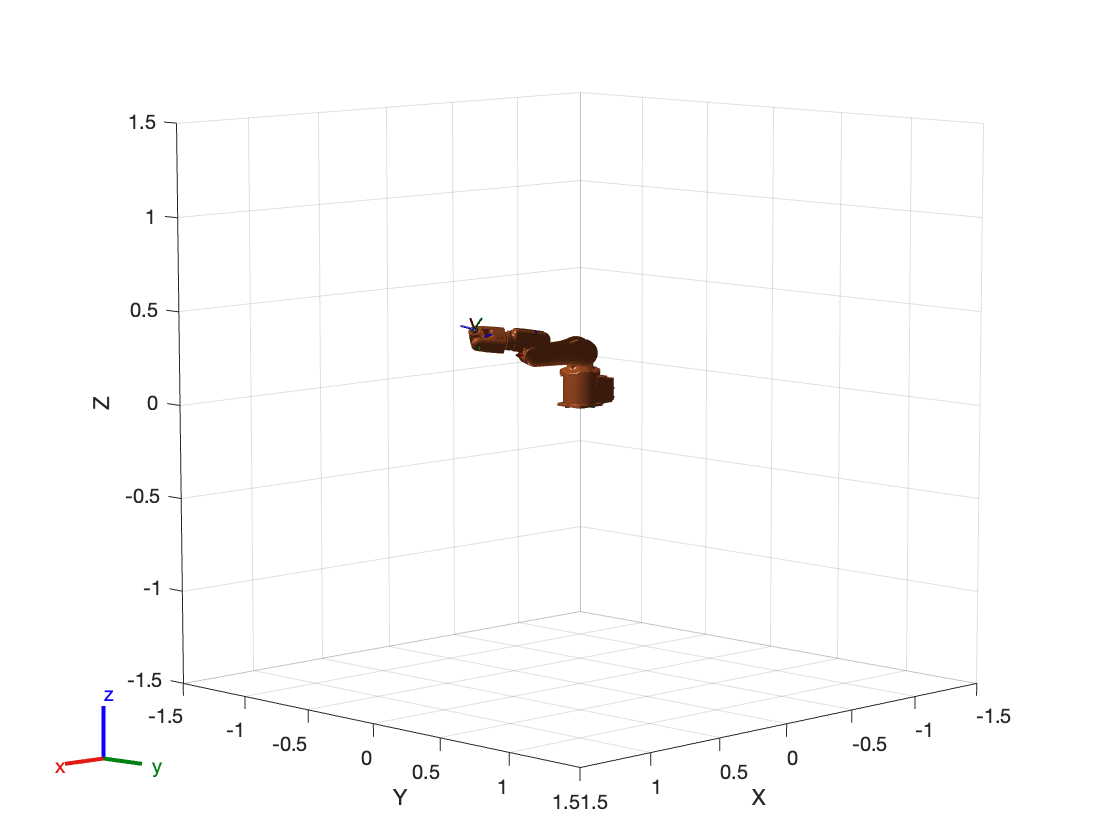

irb120.DataFormat = 'row';
    
rate = rateControl(size(intPath,1));

figure(5)
for i = 1:1:size(intPath,1)
    show(irb120,intPath(i,:),"PreservePlot",false, "FastUpdate",true);
    waitfor(rate);
end

## Trajectory Generation

Trajectory planning is the process of producing reference inputs for the motion control system that follows the planned path. The manipulator must at the very least be able to finish the desired trajectory. The trajectory planner must take into account dynamic and differential restrictions because the path only meets kinematic constraints. Trajectory planning algorithms must provide smooth trajectories that comply to the manipulator's actuator constraints. Trajectory planning can be done in both joint and task space.

Further information about joint vs task space trajectories and the different types of trajectories used in this section can be found here: [Trajectory Explainer](https://blogs.mathworks.com/student-lounge/2019/11/06/robot-manipulator-trajectory/)  [Video Explainer](https://uk.mathworks.com/videos/trajectory-planning-for-robot-manipulators-1556705635398.html)

#### Joint-Space Trajectories

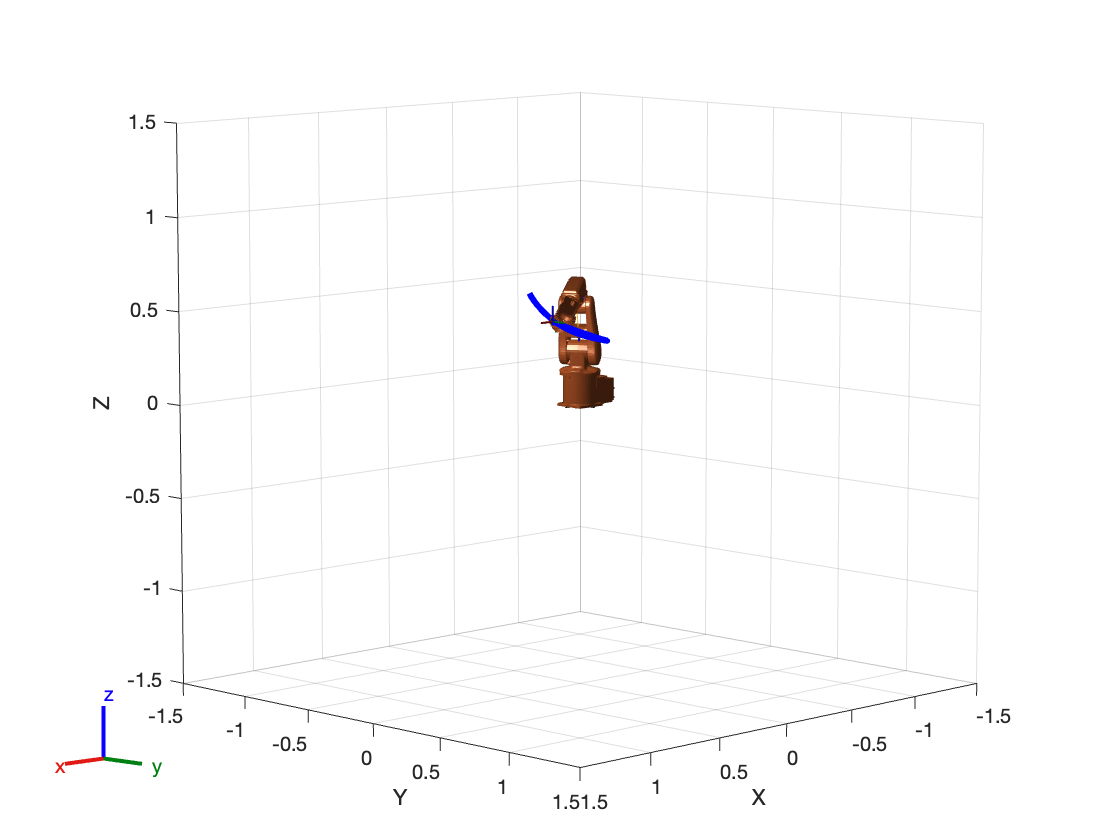

irb120.DataFormat = 'column';

% Define Joint Configuration Waypoints
    point1 = home';
    point2 = [1.2611 0.5263 0.1111 -1.7590 1.3233 2.2317]';
    point3 = [0.5475 0.2929 0.0918 -2.1226 0.6577 2.2319]';
    waypointsj = [point1 point2 point3];

% Create Time Points for the Trajectory
    sampleRate = 20;
    time_points = 0:1:(size(waypointsj,2)-1);
    time_vecj = time_points(1):1/sampleRate:time_points(end);
    numSample = length(time_vecj);

% Generate Trajectory using different trajectory generators
    rng(0);
    qj = zeros(6,numSample);
    qd = zeros(6,numSample);
    qdd = zeros(6,numSample);

    trajgen = "cubic";

    if trajgen == 'trap'
        [qj,qjd,qdd] = trapveltraj(waypointsj,numSample);
    elseif trajgen == 'cubic'
        [qj,qjd,qdd] = cubicpolytraj(waypointsj,time_points,time_vecj);
    else
        [qj,qjd,qdd] = minjerkpolytraj(waypointsj,[0,1],numSample);
    end

% Display Trajectory
    rate = rateControl(sampleRate);
    figure(6)
    for i = 1:numSample
        show(irb120,qj(:,i),FastUpdate=true,PreservePlot=false);
        eePositj(i,:) = tform2trvec(getTransform(irb120,qj(:,i),"link_6"));
        waitfor(rate);
    end
    hold on
    plot3(eePositj(:,1),eePositj(:,2),eePositj(:,3),'b-','LineWidth',3);

#### Task-Space Trajectories

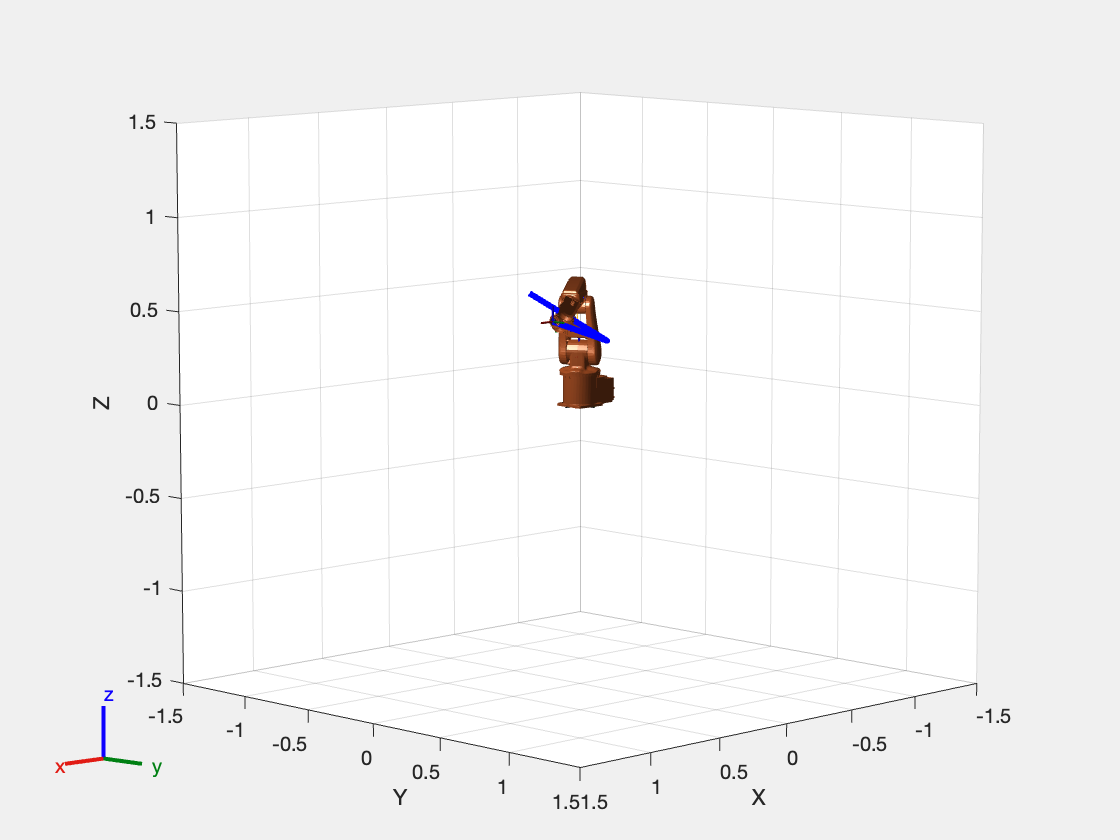

% Define Cartesian Waypoints and Time Points
    waypointst = [0.374 0 0.63; 0.2 0.4 0.4; 0.4 0.2 0.5]';
    Timepoints = 0:1:(size(waypointst,2)-1);
    time_vect = Timepoints(1):1/sampleRate:Timepoints(end);
    numSample = length(time_vect);

% Generate Trajectory

    trajgen = "cubic";

    if trajgen == 'trap'
        [pos,vel,acc] = trapveltraj(waypoints,numSample);
    elseif trajgen == 'cubic'
        [pos,vel,acc] = cubicpolytraj(waypoints,Timepoints,time_vect);
    else
        [pos,vel,acc] = minjerkpolytraj(waypoints,Timepoints,numSample);
    end

% Calculate Joint Configuration at each point along trajectory

    qt = zeros(6,numSample);

% Uncomment to use numerical solver
% weight = [0.2 0.2 0.2 1 1 1];
% initialguess = home;

    for i = 1:size(pos,2)
        targetpose = trvec2tform(pos(:,i)')*rotm2tform([1 0 0; 0 1 0; 0 0 1]);
        configSoln = robotIK(targetpose);
        %[configSoln ,solnInfo] = Nik('link_6', targetpose,weight,initialguess);
        qt(:,i) = configSoln(1,:)';
        %initialguess = q(:,i);
    end

% Display Trajectory
    eePosit = zeros(numSample,3);
    figure(7)
    set(gcf,"Visible","on")
    for i = 1:numSample
        show(irb120, qt(:,i),FastUpdate=true,PreservePlot=false);
        eePositt(i,:) = tform2trvec(getTransform(irb120,qt(:,i),"link_6"));
        waitfor(rate);
    end
    hold on
    plot3(eePositt(:,1),eePositt(:,2),eePositt(:,3),'b-','LineWidth',3);

## Comparing Various Trajectories

This section looks at comparing the previously generated trajectories. Here, the angles of each joint is plotted over time aswell as the position and speed of the end-effector over the duration of the movement. These graphs can be used to compare the various trajectories to each other as well as comparing joint-space trajectories to task-space trajectories.

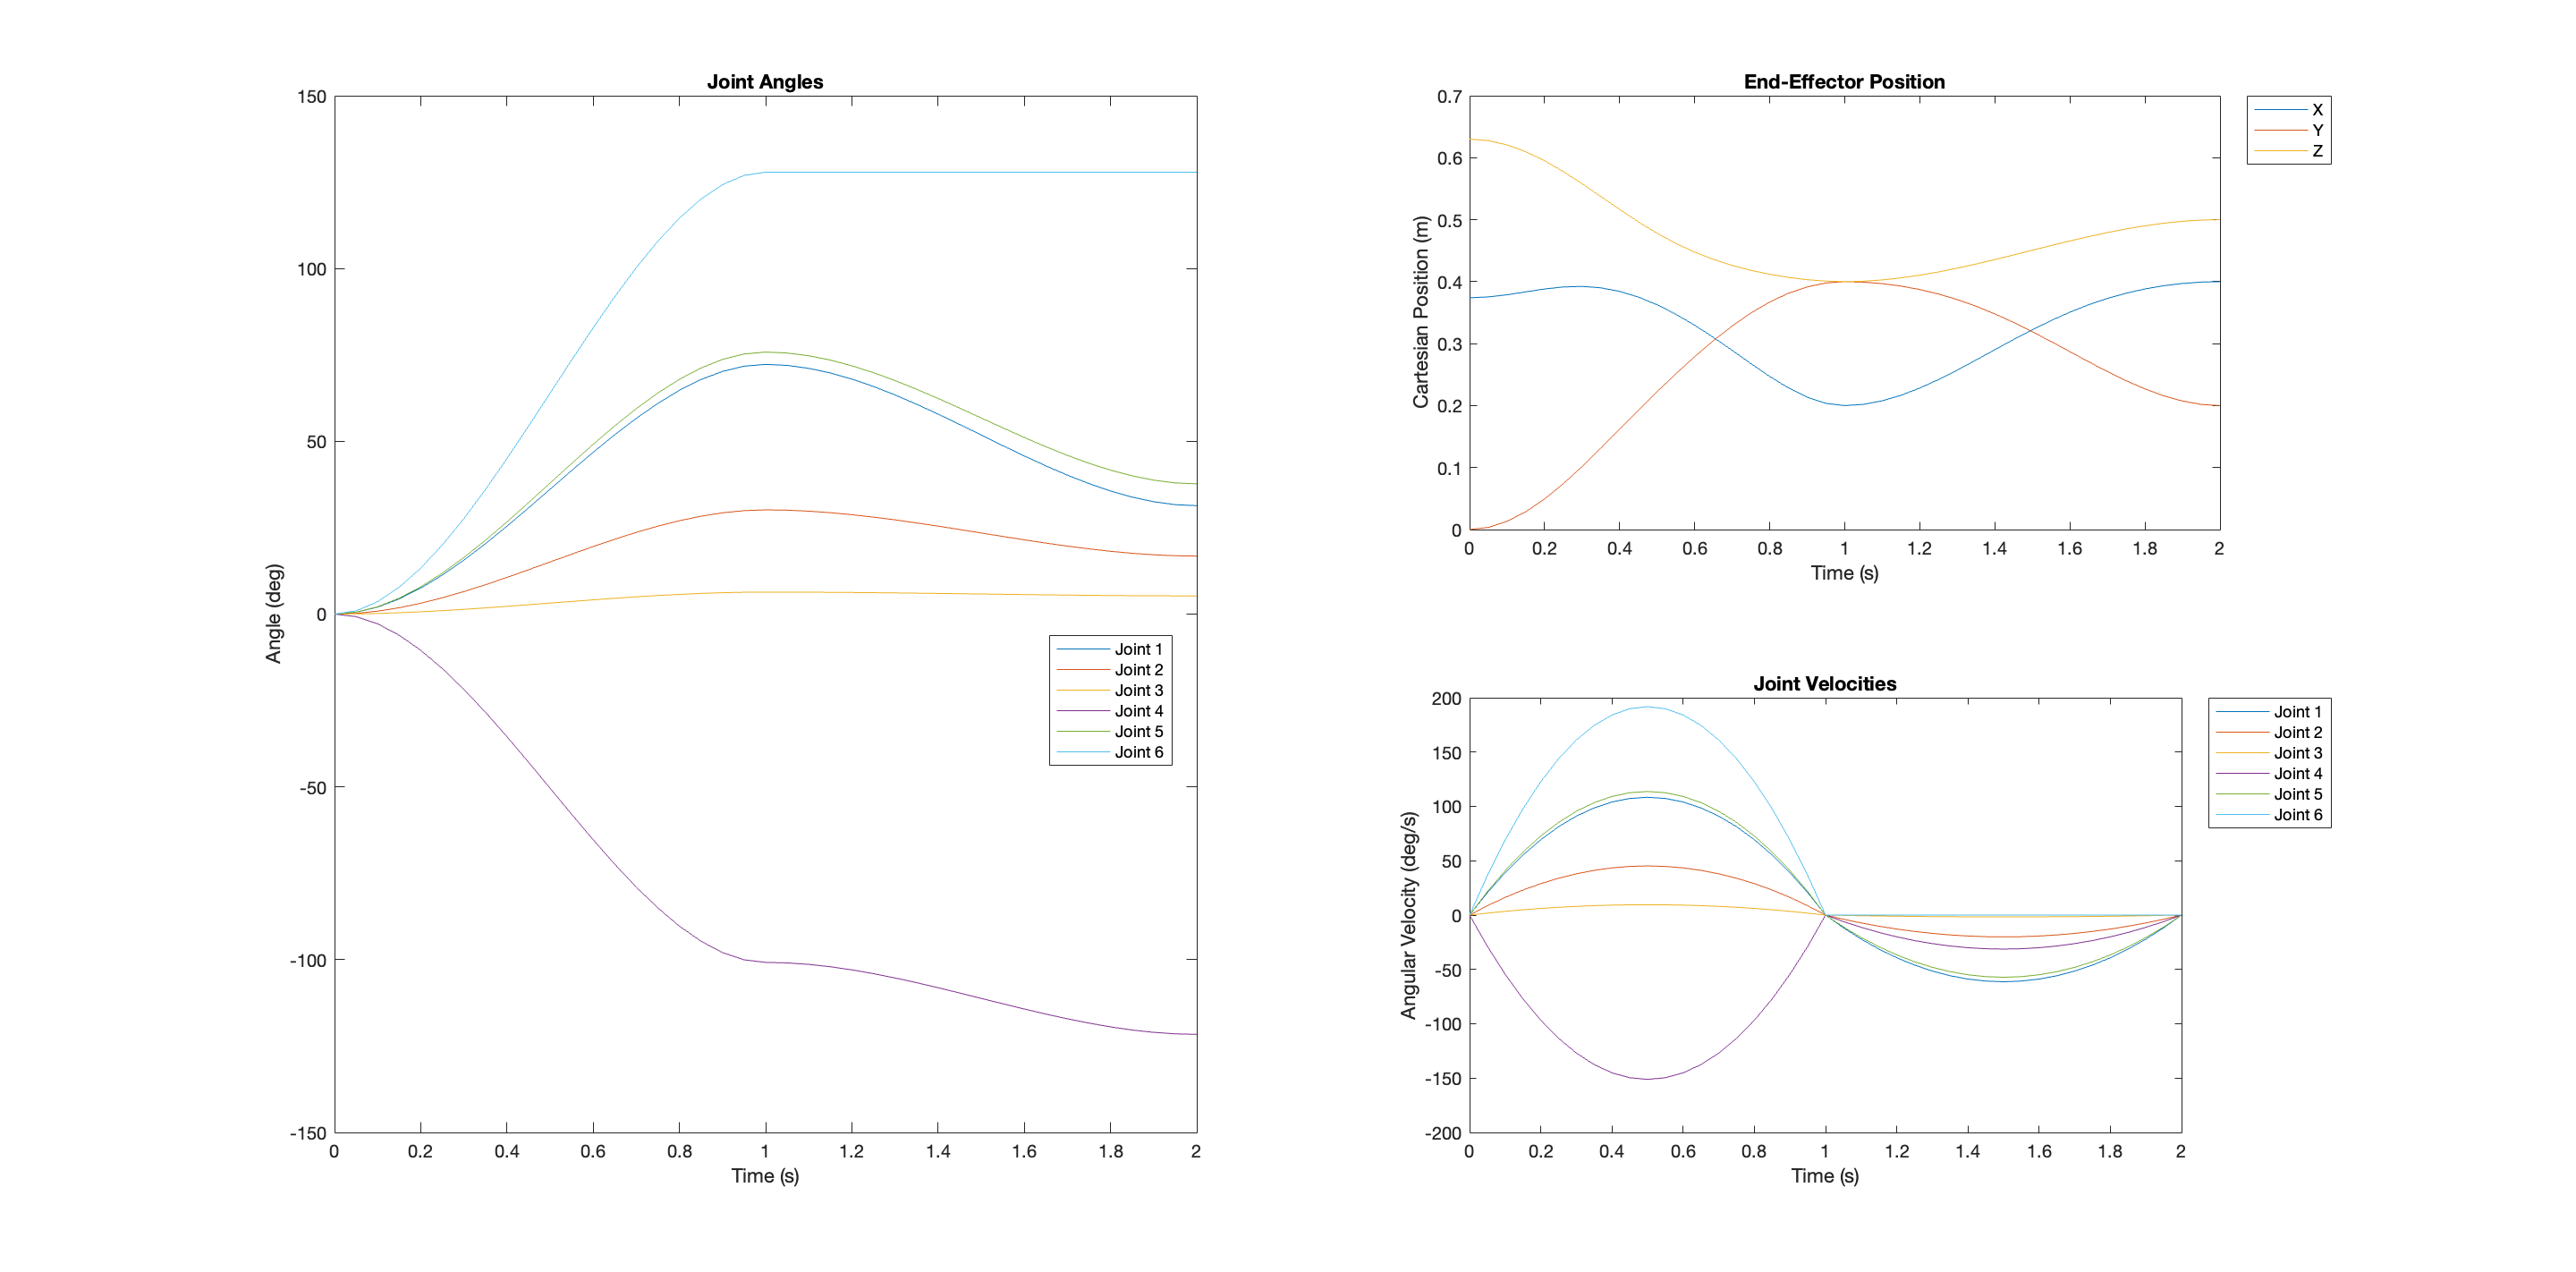

% Joint-Space Trajectory
figure(8)
hold on
% Joint Angle Plot
subplot(2,2,[1 3])
set(gcf,"Visible","on", 'position',[0,0,1500,1000])
plot(time_vecj, rad2deg(qj))
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6', 'Location','best')
title('Joint Angles')
xlabel('Time (s)')
ylabel('Angle (deg)')
% End-Effector Position Plot
subplot(2,2,2)
plot(time_vecj, eePositj)
legend('X','Y','Z', 'Location','northeastoutside')
title('End-Effector Position')
xlabel('Time (s)')
ylabel('Cartesian Position (m)')
subplot(2,2,4)
plot(time_vecj, rad2deg(qjd))
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6', 'Location','northeastoutside')
title('Joint Velocities')
xlabel('Time (s)')
ylabel('Angular Velocity (deg/s)')

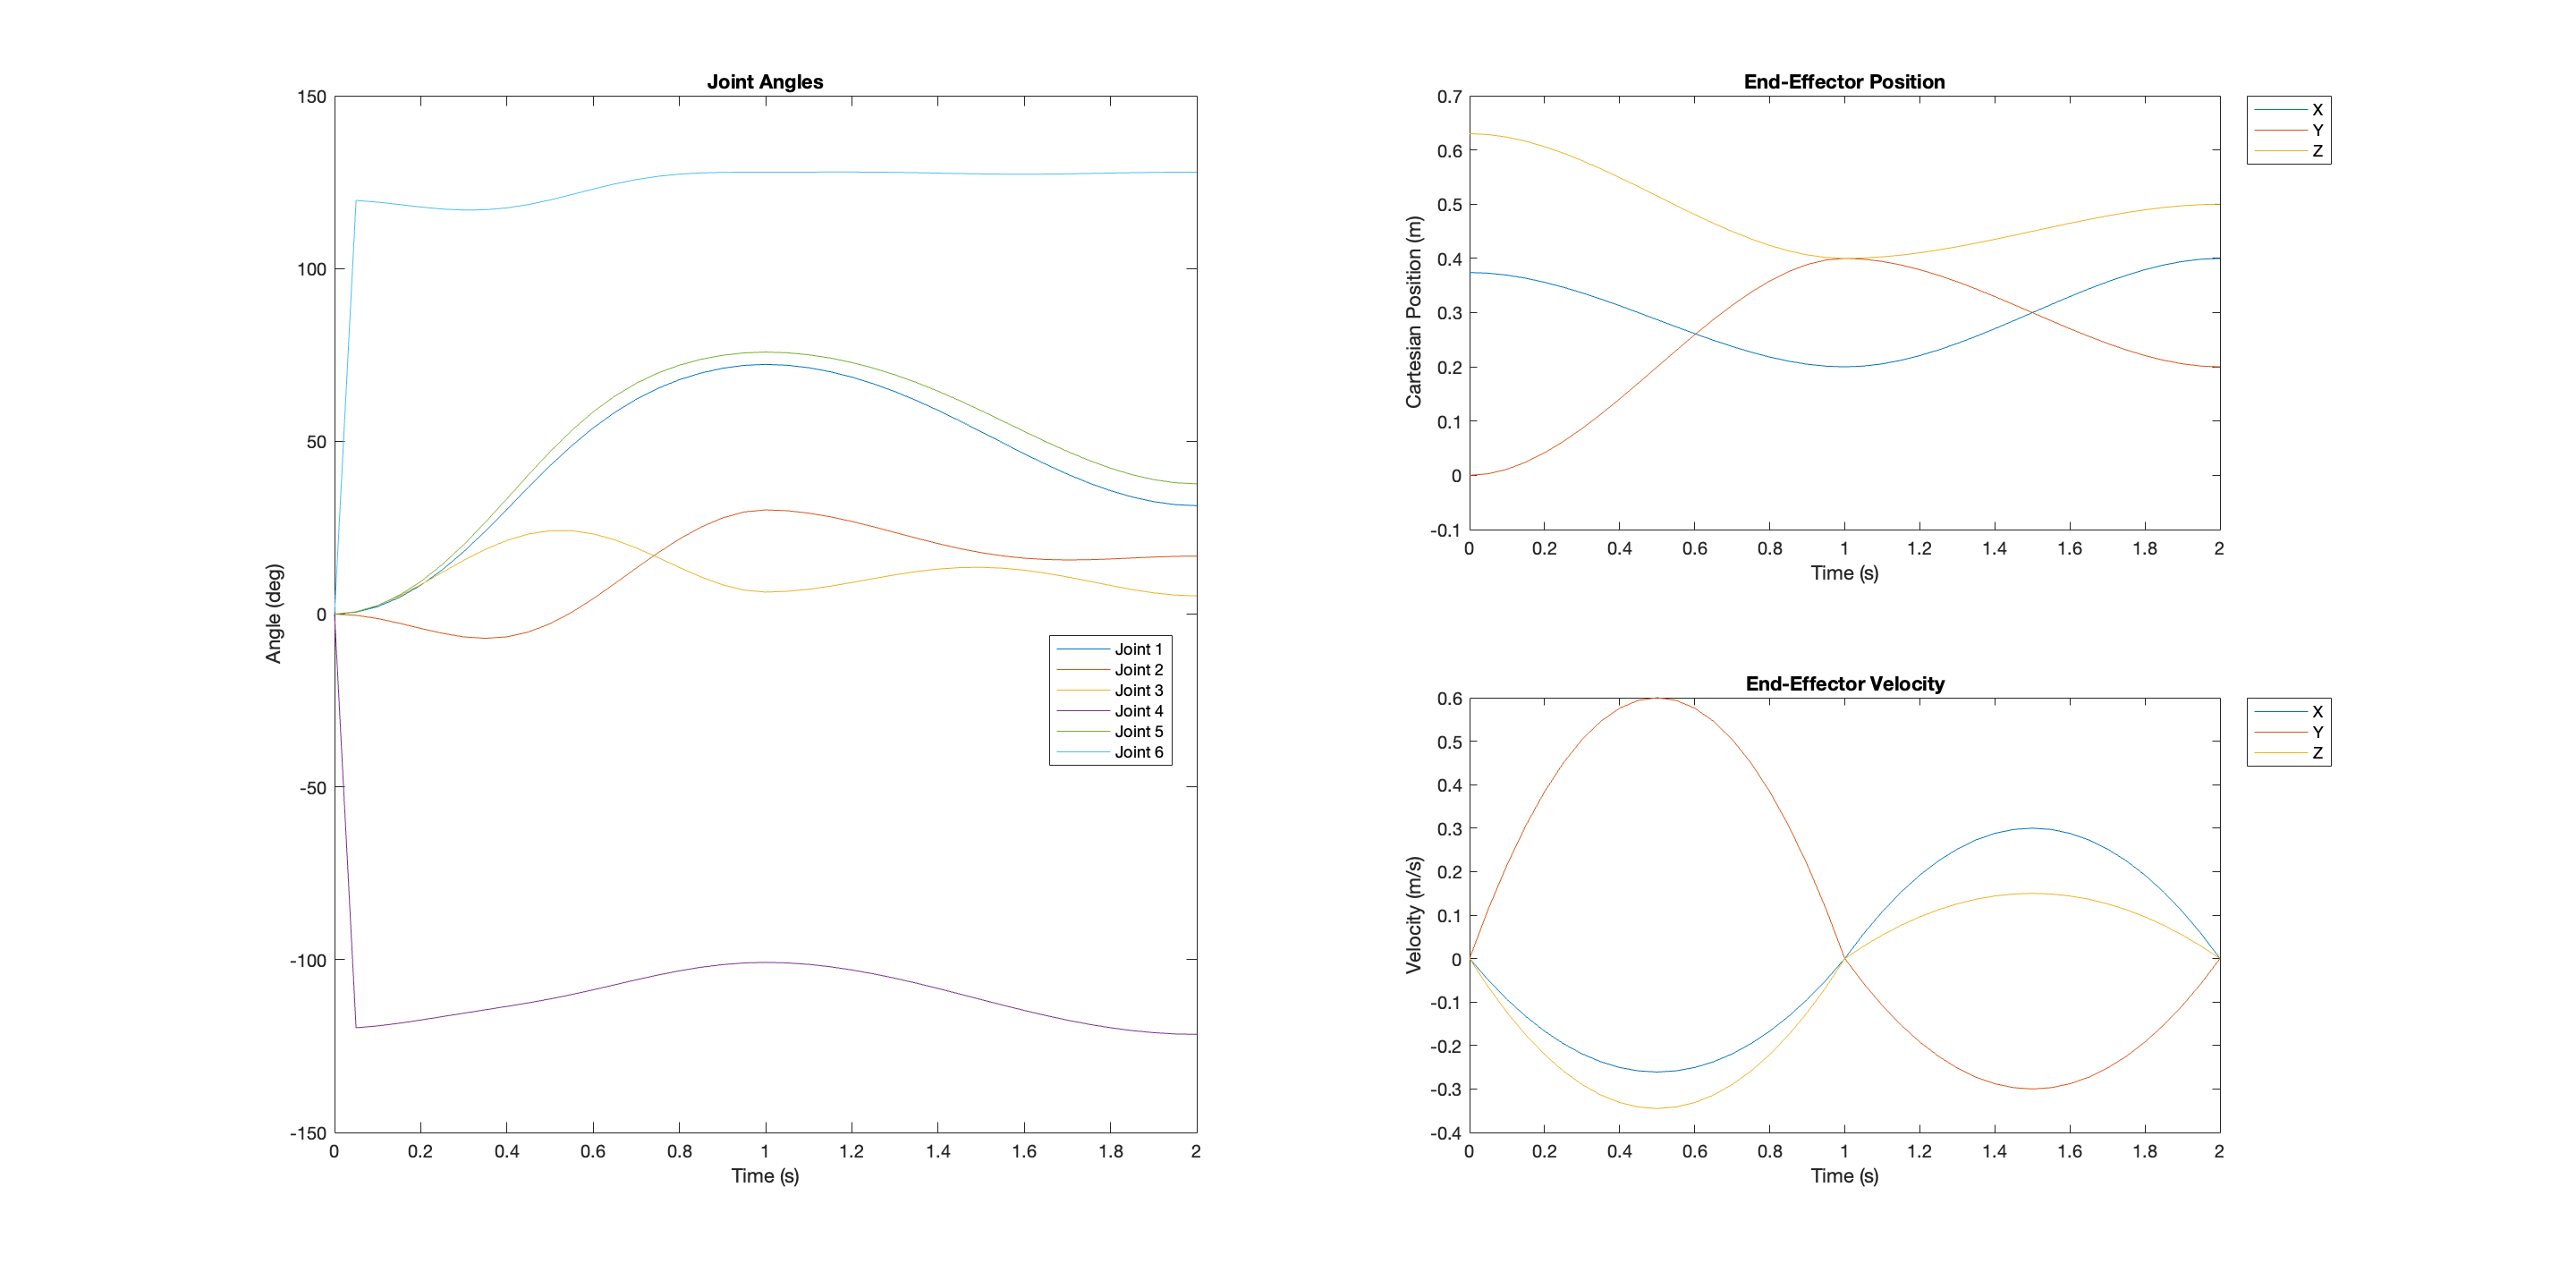


% Task-Space Trajectory
figure(9)
hold on
% Joint Angle Plot
subplot(2,2,[1 3])
set(gcf,"Visible","on", 'position',[0,0,1500,1000])
plot(time_vect, rad2deg(qt))
legend('Joint 1','Joint 2','Joint 3','Joint 4','Joint 5','Joint 6', 'Location','best')
title('Joint Angles')
xlabel('Time (s)')
ylabel('Angle (deg)')
% End-Effector Position Plot
subplot(2,2,2)
plot(time_vect, eePositt)
legend('X','Y','Z', 'Location','northeastoutside')
title('End-Effector Position')
xlabel('Time (s)')
ylabel('Cartesian Position (m)')
subplot(2,2,4)
plot(time_vect, vel)
legend('X','Y','Z', 'Location','northeastoutside')
title('End-Effector Velocity')
xlabel('Time (s)')
ylabel('Velocity (m/s)')